clear
A=sym([0 0])

$$A = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

B=sym([1 3])

$$B = \left(\begin{array}{cc} 1 & 3 \end{array}\right)$$

C=sym([7 1])

$$C = \left(\begin{array}{cc} 7 & 1 \end{array}\right)$$

hold on
plot(A(1),A(2),'ro')
plot(B(1),B(2),'go')
plot(C(1),C(2),'bo')
grid
Lab=line2p(A,B)

$$Lab = 3\,x=y$$

Lbc=line2p(B,C)

$$Lbc = x+3\,y=10$$

kab=sym(3),kcd=kab

$$kab = 3$$

$$kcd = 3$$

kbc=sym(-1/3),kad=kbc

$$kbc = -\frac{1}{3}$$

$$kad = -\frac{1}{3}$$

% Найдем угол ABC
kab*kbc

$$ans = -1$$

% AB и BC ортогональны

% Достраиваем недостающие стороны
syms x y x1 y1 k
L=y-y1==k*(x-x1)

$$L = y-y_{1}=k\,\left(x-x_{1}\right)$$

Lcd=subs(L,[k x1 y1],[kcd C])

$$Lcd = y-1=3\,x-21$$

Lad=subs(L,[k x1 y1],[kad A])

$$Lad = y=-\frac{x}{3}$$

% 4-я точка
[xd yd]=solve(Lad,Lcd),D=[xd yd]

$$xd = 6$$

$$yd = -2$$

$$D = \left(\begin{array}{cc} 6 & -2 \end{array}\right)$$

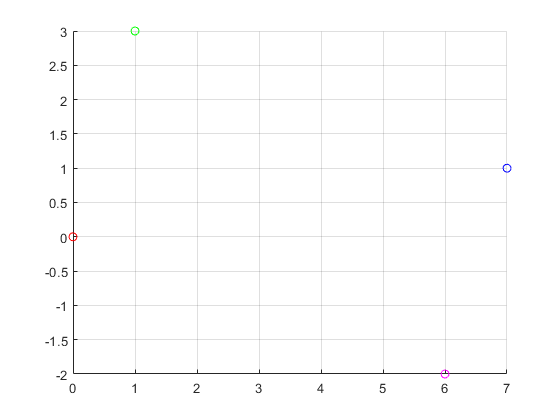

plot(D(1),D(2),'mo')
hold off

% Диагонали
Lac=line2p(A,C)

$$Lac = x=7\,y$$

Lbd=line2p(B,D)

$$Lbd = x+y=4$$

% Найдем угол между диагоналями
kac=sym(1/7),k1=kac

$$kac = \frac{1}{7}$$

$$k1 = \frac{1}{7}$$

kbd=sym(-1),k2=kbd

$$kbd = -1$$

$$k2 = -1$$

alpha=atan(abs((k2-k1)/(1+k1*k2)))

$$alpha = \mathrm{atan}\left(\frac{4}{3}\right)$$